# Modulation Classification with Deep Learning

This example shows how to use a convolutional neural network (CNN) for modulation classification. You generate synthetic, channel-impaired waveforms. Using the generated waveforms as training data, you train a CNN for modulation classification. You then test the CNN with software-defined radio (SDR) hardware and over-the-air signals.

## Predict Modulation Type Using CNN

The trained CNN in this example recognizes these eight digital and three analog modulation types: 

- Binary phase shift keying (BPSK)

- Quadrature phase shift keying (QPSK)

- 8-ary phase shift keying (8-PSK)

- 16-ary quadrature amplitude modulation (16-QAM)

- 64-ary quadrature amplitude modulation (64-QAM)

- 4-ary pulse amplitude modulation (PAM4)

- Gaussian frequency shift keying (GFSK)

- Continuous phase frequency shift keying (CPFSK)

- Broadcast FM (B-FM)

- Double sideband amplitude modulation (DSB-AM)

- Single sideband amplitude modulation (SSB-AM)

modulationTypes = categorical(["BPSK", "QPSK", "8PSK", ...
  "16QAM", "64QAM", "PAM4", "GFSK", "CPFSK", ...
  "B-FM", "DSB-AM", "SSB-AM"]);

First, load the trained network. For details on network training, see the Training a CNN section.

load trainedModulationClassificationNetwork
trainedNet

The trained CNN takes 1024 channel-impaired samples and predicts the modulation type of each frame. Generate several PAM4 frames that are impaired with Rician multipath fading, center frequency and sampling time drift, and AWGN. Use following function  to generate synthetic signals to test the CNN. Then use the CNN to predict the modulation type of the frames.

- [randi](docid:matlab_ref#buf2csg):  Generate random bits

- [pammod:](docid:comm_ref#a1042480014b1) PAM4-modulate the bits

- [rcosdesign](docid:signal_ref#bt00vcn): Design a square-root raised cosine pulse shaping filter

- [filter](docid:matlab_ref#bt_vs4t-1): Pulse shape the symbols

- [comm.RicianChannel](docid:comm_ref#btzx8bh-1): Apply Rician multipath channel

- [comm.PhaseFrequencyOffset](docid:comm_ref#bsnfizs_4): Apply phase and/or frequency shift due to clock offset

- [interp1](docid:matlab_ref#btwp6lt-1): Apply timing drift due to clock offset

- [awgn](docid:comm_ref#fp1221678): Add AWGN

% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(123456)
% Random bits
d = randi([0 3], 1024, 1);
% PAM4 modulation
syms = pammod(d,4);
% Square-root raised cosine filter
filterCoeffs = rcosdesign(0.35,4,8);
tx = filter(filterCoeffs,1,upsample(syms,8));

% Channel
SNR = 30;
maxOffset = 5;
fc = 902e6;
fs = 200e3;
multipathChannel = comm.RicianChannel(...
  'SampleRate', fs, ...
  'PathDelays', [0 1.8 3.4] / 200e3, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4);

frequencyShifter = comm.PhaseFrequencyOffset(...
  'SampleRate', fs);

% Apply an independent multipath channel
reset(multipathChannel)
outMultipathChan = multipathChannel(tx);

% Determine clock offset factor
clockOffset = (rand() * 2*maxOffset) - maxOffset;
C = 1 + clockOffset / 1e6;

% Add frequency offset
frequencyShifter.FrequencyOffset = -(C-1)*fc;
outFreqShifter = frequencyShifter(outMultipathChan);

% Add sampling time drift
t = (0:length(tx)-1)' / fs;
newFs = fs * C;
tp = (0:length(tx)-1)' / newFs;
outTimeDrift = interp1(t, outFreqShifter, tp);

% Add noise
rx = awgn(outTimeDrift,SNR,0);

% Frame generation for classification
unknownFrames = helperModClassGetNNFrames(rx);

% Classification
[prediction1,score1] = classify(trainedNet,unknownFrames);

Return the classifier predictions, which are analogous to hard decisions. The network correctly identifies the frames as PAM4 frames. For details on the generation of the modulated signals, see [helperModClassGetModulator](matlab:openExample('ModulationClassificationWithDeepLearningExample', 'supportingFile', 'helperModClassGetModulator')) function.

prediction1

The classifier also returns a vector of scores for each frame.  The score corresponds to the probability that each frame has the predicted modulation type. Plot the scores.

helperModClassPlotScores(score1,modulationTypes)

Before we can use a CNN for modulation classification, or any other task, we first need to train the network with known (or labeled) data. The first part of this example shows how to use Communications Toolbox features, such as modulators, filters, and channel impairments, to generate synthetic training data. The second part focuses on defining, training, and testing the CNN for the task of modulation classification. The third part tests the network performance with over-the-air signals using software defined radio (SDR) platforms.

## Waveform Generation for Training

Generate 10,000 frames for each modulation type, where 80% is used for training, 10% is used for validation and 10% is used for testing. We use training and validation frames during the network training phase. Final classification accuracy is obtained using test frames. Each frame is 1024 samples long and has a sample rate of 200 kHz. For digital modulation types, eight samples represent a symbol. The network makes each decision based on single frames rather than on multiple consecutive frames (as in video). Assume a center frequency of 902 MHz and 100 MHz for the digital and analog modulation types, respectively.

To run this example quickly, use the trained network and generate a small number of training frames. To train the network on your computer, choose the "Train network now" option (i.e. set trainNow to true).

trainNow = false;
if trainNow == true
  numFramesPerModType = 10000;
else
  numFramesPerModType = 500;
end
percentTrainingSamples = 80;
percentValidationSamples = 10;
percentTestSamples = 10;

sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
fs = 200e3;             % Sample rate
fc = [902e6 100e6];     % Center frequencies

### Create Channel Impairments

Pass each frame through a channel with

- AWGN

- Rician multipath fading

- Clock offset, resulting in center frequency offset and sampling time drift

Because the network in this example makes decisions based on single frames, each frame must pass through an independent channel. 

#### AWGN

The channel adds AWGN with an SNR of 30 dB. Implement the channel using [awgn](docid:comm_ref#fp1221678) function. 

#### Rician Multipath

The channel passes the signals through a Rician multipath fading channel using the [comm.RicianChannel](docid:comm_ref#btzx8bh-1) System object. Assume a delay profile of [0 1.8 3.4] samples with corresponding average path gains of [0 -2 -10] dB. The K-factor is 4 and the maximum Doppler shift is 4 Hz, which is equivalent to a walking speed at 902 MHz. Implement the channel with the following settings. 

#### Clock Offset

Clock offset occurs because of the inaccuracies of internal clock sources of transmitters and receivers. Clock offset causes the center frequency, which is used to downconvert the signal to baseband, and the digital-to-analog converter sampling rate to differ from the ideal values. The channel simulator uses the clock offset factor $C$, expressed as $C=1+\frac{\Delta_{\textrm{clock}} }{{10}^6 }$, where $\Delta_{\textrm{clock}}$ is the clock offset. For each frame, the channel generates a random $\Delta_{\textrm{clock}}$ value from a uniformly distributed set of values in the range [${-\max \Delta }_{\textrm{clock}}$ ${\max \Delta }_{\textrm{clock}}$], where ${\max \Delta }_{\textrm{clock}}$ is the maximum clock offset. Clock offset is measured in parts per million (ppm). For this example, assume a maximum clock offset of 5 ppm.

maxDeltaOff = 5;
deltaOff = (rand()*2*maxDeltaOff) - maxDeltaOff;
C = 1 + (deltaOff/1e6);

**Frequency Offset**

Subject each frame to a frequency offset based on clock offset factor $C$ and the center frequency. Implement the channel using [comm.PhaseFrequencyOffset](docid:comm_ref#bsnfizs_4).

**Sampling Rate Offset**

Subject each frame to a sampling rate offset based on clock offset factor $C$. Implement the channel using the [interp1](docid:matlab_ref#btwp6lt-1) function to resample the frame at the new rate of $C\times f_s$.

#### Combined Channel

Use the [helperModClassTestChannel](matlab:edit('helperModClassTestChannel.m')) object to apply all three channel impairments to the frames. 

channel = helperModClassTestChannel(...
  'SampleRate', fs, ...
  'SNR', SNR, ...
  'PathDelays', [0 1.8 3.4] / fs, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4, ...
  'MaximumClockOffset', 5, ...
  'CenterFrequency', 902e6)

You can view basic information about the channel using the info object function.

chInfo = info(channel)

### Waveform Generation

Create a loop that generates channel-impaired frames for each modulation type and stores the frames with their corresponding labels in MAT files. By saving the data into files, you eliminate the need to generate the data every time you run this example. You can also share the data more effectively. 

Remove a random number of samples from the beginning of each frame to remove transients and to make sure that the frames have a random starting point with respect to the symbol boundaries. 

% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(1235)
tic

numModulationTypes = length(modulationTypes);

channelInfo = info(channel);
transDelay = 50;
dataDirectory = fullfile(tempdir,"ModClassDataFiles");
disp("Data file directory is " + dataDirectory)
fileNameRoot = "frame";

% Check if data files exist
dataFilesExist = false;
if exist(dataDirectory,'dir')
  files = dir(fullfile(dataDirectory,sprintf("%s*",fileNameRoot)));
  if length(files) == numModulationTypes*numFramesPerModType
    dataFilesExist = true;
  end
end

if ~dataFilesExist
  disp("Generating data and saving in data files...")
  [success,msg,msgID] = mkdir(dataDirectory);
  if ~success
    error(msgID,msg)
  end
  for modType = 1:numModulationTypes
    fprintf('%s - Generating %s frames\n', ...
      datestr(toc/86400,'HH:MM:SS'), modulationTypes(modType))
    
    label = modulationTypes(modType);
    numSymbols = (numFramesPerModType / sps);
    dataSrc = helperModClassGetSource(modulationTypes(modType), sps, 2*spf, fs);
    modulator = helperModClassGetModulator(modulationTypes(modType), sps, fs);
    if contains(char(modulationTypes(modType)), {'B-FM','DSB-AM','SSB-AM'})
      % Analog modulation types use a center frequency of 100 MHz
      channel.CenterFrequency = 100e6;
    else
      % Digital modulation types use a center frequency of 902 MHz
      channel.CenterFrequency = 902e6;
    end
    
    for p=1:numFramesPerModType
      % Generate random data
      x = dataSrc();
      
      % Modulate
      y = modulator(x);
      
      % Pass through independent channels
      rxSamples = channel(y);
      
      % Remove transients from the beginning, trim to size, and normalize
      frame = helperModClassFrameGenerator(rxSamples, spf, spf, transDelay, sps);
      
      % Save data file
      fileName = fullfile(dataDirectory,...
        sprintf("%s%s%03d",fileNameRoot,modulationTypes(modType),p));
      save(fileName,"frame","label")
    end
  end
else
  disp("Data files exist. Skip data generation.")
end

% Plot the amplitude of the real and imaginary parts of the example frames
% against the sample number
helperModClassPlotTimeDomain(dataDirectory,modulationTypes,fs)

% Plot the spectrogram of the example frames
helperModClassPlotSpectrogram(dataDirectory,modulationTypes,fs,sps)

### Create a Datastore

Use a `signalDatastore` object to manage the files that contain the generated complex waveforms. Datastores are especially useful when each individual file fits in memory, but the entire collection does not necessarily fit.

frameDS = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);

### Transform Complex Signals to Real Arrays

The deep learning network in this example expects real inputs while the received signal has complex baseband samples. Transform the complex signals into real valued 4-D arrays. The output frames have size 1-by-spf-by-2-by-N, where the first page (3rd dimension) is in-phase samples and the second page is quadrature samples. When the convolutional filters are of size 1-by-spf, this approach ensures that the information in the I and Q gets mixed even in the convolutional layers and makes better use of the phase information. See [helperModClassIQAsPages](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassIQAsPages.m')) for details.

frameDSTrans = transform(frameDS,@helperModClassIQAsPages);

### Split into Training, Validation, and Test

Next divide the frames into training, validation, and test data. See [helperModClassSplitData](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassSplitData.m')) for details.

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTrans,validDSTrans,testDSTrans] = helperModClassSplitData(frameDSTrans,splitPercentages);

### Import Data Into Memory

Neural network training is iterative. At every iteration, the datastore reads data from files and transforms the data before updating the network coefficients. If the data fits into the memory of your computer, importing the data from the files into the memory enables faster training by eliminating this repeated read from file and transform process. Instead, the data is read from the files and transformed once. Training this network using data files on disk takes about 110 minutes while training using in-memory data takes about 50 min. 

Import all the data in the files into memory. The files have two variables: `frame` and `label` and each [read](docid:matlab_ref#budsyj6-1) call to the datastore returns a cell array, where the first element is the `frame` and the second element is the `label`. Use the [transfrom](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) functions [helperModClassReadFrame](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassReadFrame.m')) and [helperModClassReadLabel](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassReadLabel.m')) to read frames and labels. Use [tall](docid:matlab_ref#bvaomuj-1) arrays to enable parallel processing of the transform functions, in case you have [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html) license. Since [gather](docid:matlab_ref#bvaolov) function, by default,  concatenates the output of the `read` function over the first dimension, return the frames in a cell array and manually concatenate over the 4th dimension. 

% Gather the training and validation frames into the memory
trainFramesTall = tall(transform(trainDSTrans, @helperModClassReadFrame));
rxTrainFrames = gather(trainFramesTall);
rxTrainFrames = cat(4, rxTrainFrames{:});
validFramesTall = tall(transform(validDSTrans, @helperModClassReadFrame));
rxValidFrames = gather(validFramesTall);
rxValidFrames = cat(4, rxValidFrames{:});

% Gather the training and validation labels into the memory
trainLabelsTall = tall(transform(trainDSTrans, @helperModClassReadLabel));
rxTrainLabels = gather(trainLabelsTall);
validLabelsTall = tall(transform(validDSTrans, @helperModClassReadLabel));
rxValidLabels = gather(validLabelsTall);

## Train the CNN

This example uses a CNN that consists of six convolution layers and one fully connected layer. Each convolution layer except the last is followed by a batch normalization layer, rectified linear unit (ReLU) activation layer, and max pooling layer. In the last convolution layer, the max pooling layer is replaced with an average pooling layer. The output layer has softmax activation. For network design guidance, see [Deep Learning Tips and Tricks](docid:nnet_ug#mw_b35bb367-38bf-4597-8e6b-479a2b3c408e). 

modClassNet = helperModClassCNN(modulationTypes,sps,spf);

Next configure [trainingOptions](docid:nnet_ref#mw_8fe68f2d-556c-4a48-93ce-3a2e4c6aa518) to use an SGDM solver with a mini-batch size of 256. Set the maximum number of epochs to 12, since a larger number of epochs provides no further training advantage. By default, the `'ExecutionEnvironment'` property is set to `'auto'`, where the `trainNetwork` function uses a GPU if one is available or uses the CPU, if not. To use the GPU, you must have a [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html) license. Set the initial learning rate to $2x{10}^{-2}$. Reduce the learning rate by a factor of 10 every 9 epochs. Set `'Plots'` to '`training-progress'` to plot the training progress. On an NVIDIA Titan Xp GPU, the network takes approximately 25 minutes to train. . 

maxEpochs = 12;
miniBatchSize = 256;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels);

Either train the network or use the already trained network. By default, this example uses the trained network.

if trainNow == true
  fprintf('%s - Training the network\n', datestr(toc/86400,'HH:MM:SS'))
  trainedNet = trainNetwork(rxTrainFrames,rxTrainLabels,modClassNet,options);
else
  load trainedModulationClassificationNetwork
end

As the plot of the training progress shows, the network converges in about 12 epochs to more than 95% accuracy.  

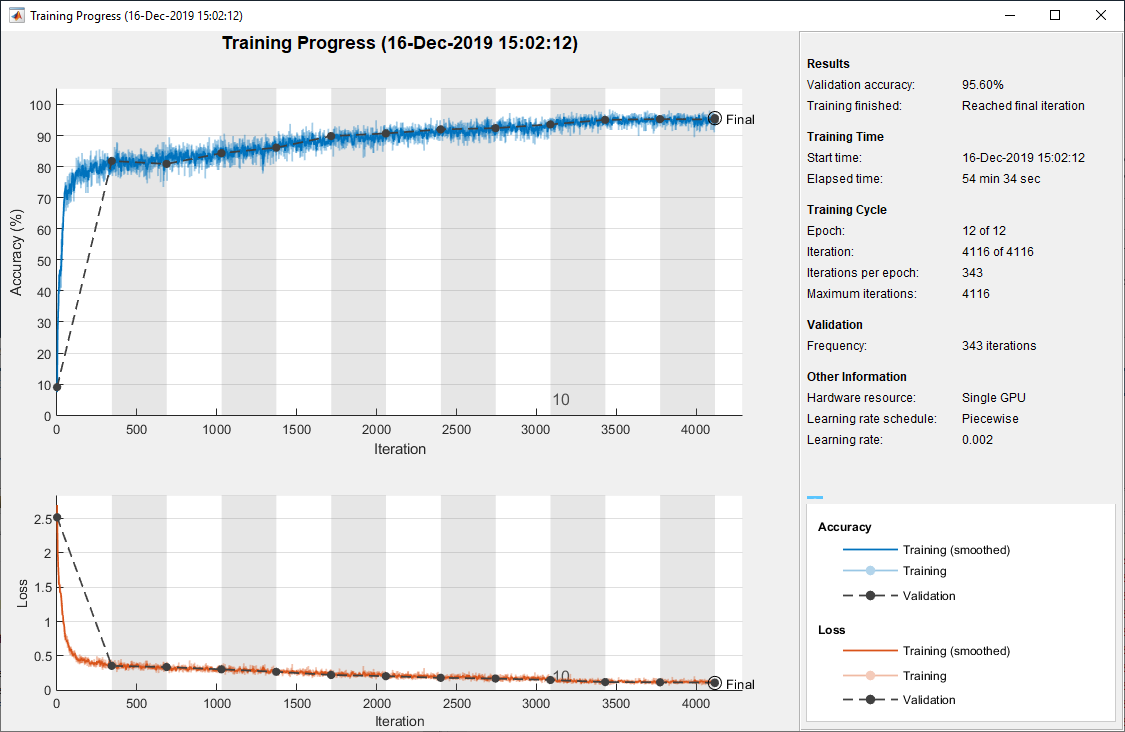

Evaluate the trained network by obtaining the classification accuracy for the test frames. The results show that the network achieves about 94% accuracy for this group of waveforms.

fprintf('%s - Classifying test frames\n', datestr(toc/86400,'HH:MM:SS'))
% Gather the test frames into the memory
testFramesTall = tall(transform(testDSTrans, @helperModClassReadFrame));
rxTestFrames = gather(testFramesTall);
rxTestFrames = cat(4, rxTestFrames{:});

% Gather the test labels into the memory
testLabelsTall = tall(transform(testDSTrans, @helperModClassReadLabel));
rxTestLabels = gather(testLabelsTall);

rxTestPred = classify(trainedNet,rxTestFrames);
testAccuracy = mean(rxTestPred == rxTestLabels);
disp("Test accuracy: " + testAccuracy*100 + "%")

Plot the confusion matrix for the test frames. As the matrix shows, the network confuses 16-QAM and 64-QAM frames. This problem is expected since each frame carries only 128 symbols and 16-QAM is a subset of 64-QAM. The network also confuses QPSK and 8-PSK frames, since the constellations of these modulation types look similar once phase-rotated due to the fading channel and frequency offset. 

figure
cm = confusionchart(rxTestLabels, rxTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 740 424];

## Test with SDR

Test the performance of the trained network with over-the-air signals using the [helperModClassSDRTest](matlab:openExample('ModulationClassificationWithDeepLearningExample','supportingFile', 'helperModClassSDRTest')) function. To perform this test, you must have dedicated SDRs for transmission and reception. You can use two ADALM-PLUTO radios, or one ADALM-PLUTO radio for transmission and one USRP® radio for reception. You must install [Communications Toolbox Support Package for ADALM-PLUTO Radio](matlab:matlab.internal.addons.launchers.showExplorer("CT_EXAMPLE", "identifier", "PLUTO")). If you are using a USRP® radio, you must also install [Communications Toolbox Support Package for USRP® Radio](matlab:matlab.internal.addons.launchers.showExplorer("CT_EXAMPLE", "identifier", "USRP")). The `helperModClassSDRTest` function uses the same modulation functions as used for generating the training signals, and then transmits them using an ADALM-PLUTO radio. Instead of simulating the channel, capture the channel-impaired signals using the SDR that is configured for signal reception (ADALM-PLUTO or USRP® radio). Use the trained network with the same `classify` function used previously to predict the modulation type. Running the next code segment produces a confusion matrix and prints out the test accuracy.

radioPlatform = "ADALM-PLUTO";

switch radioPlatform
  case "ADALM-PLUTO"
    if helperIsPlutoSDRInstalled() == true
      radios = findPlutoRadio();
      if length(radios) >= 2
        helperModClassSDRTest(radios);
      else
        disp('Selected radios not found. Skipping over-the-air test.')
      end
    end
  case {"USRP B2xx","USRP X3xx","USRP N2xx"}
    if (helperIsUSRPInstalled() == true) && (helperIsPlutoSDRInstalled() == true)
      txRadio = findPlutoRadio();
      rxRadio = findsdru();
      switch radioPlatform
        case "USRP B2xx"
          idx = contains({rxRadio.Platform}, {'B200','B210'});
        case "USRP X3xx"
          idx = contains({rxRadio.Platform}, {'X300','X310'});
        case "USRP N2xx"
          idx = contains({rxRadio.Platform}, 'N200/N210/USRP2');
      end
      rxRadio = rxRadio(idx);
      if (length(txRadio) >= 1) && (length(rxRadio) >= 1)
        helperModClassSDRTest(rxRadio);
      else
        disp('Selected radios not found. Skipping over-the-air test.')
      end
    end
end

When using two stationary ADALM-PLUTO radios separated by about 2 feet, the network achieves 99% overall accuracy with the following confusion matrix. Results will vary based on experimental setup.

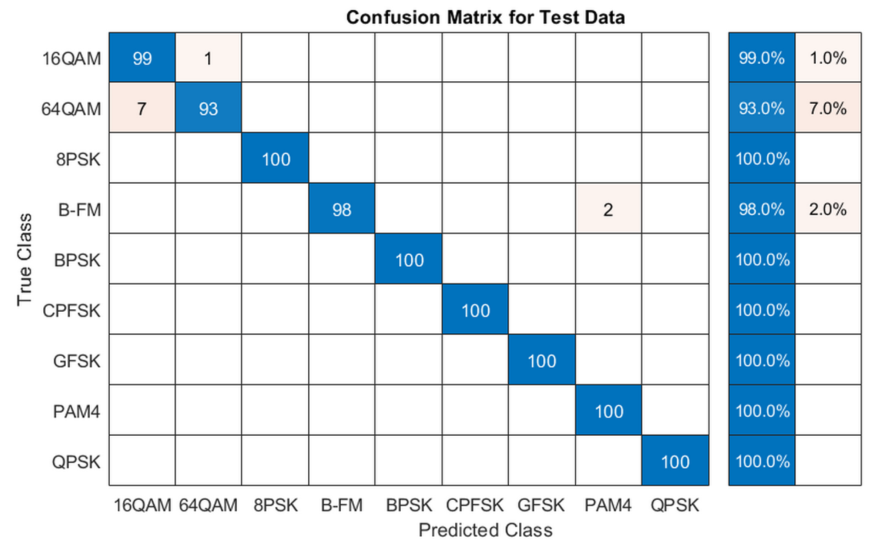

## Further Exploration

It is possible to optimize the hyperparameters parameters, such as number of filters, filter size, or optimize the network structure, such as adding more layers, using different activation layers, etc. to improve the accuracy.

Communication Toolbox provides many more modulation types and channel impairments. For more information see [Modulation](docid:comm_doccenter#bux6r2_) and [Propagation and Channel Models](docid:comm_doccenter#mw_bfe84307-08ed-4062-a764-5df9714ea7c7) sections. You can also add standard specific signals with [LTE Toolbox](https://www.mathworks.com/products/lte.html), [WLAN Toolbox](https://www.mathworks.com/products/wlan.html), and [5G Toolbox](https://www.mathworks.com/products/5g.html). You can also add radar signals with [Phased Array System Toolbox](https://www.mathworks.com/products/phased-array.html). 

[helperModClassGetModulator](matlab:openExample('ModulationClassificationWithDeepLearningExample', 'supportingFile', 'helperModClassGetModulator')) function provides the MATLAB functions used to generate modulated signals. You can also explore the following functions and System objects for more details:

- [helperModClassGetModulator.m](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassGetModulator.m'))

- [helperModClassTestChannel.m](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassTestChannel.m'))

- [helperModClassGetSource.m](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassGetSource.m'))

- [helperModClassFrameGenerator.m](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassFrameGenerator.m'))

- [helperModClassCNN.m](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassCNN.m'))

- [helperModClassTrainingOptions.m](matlab:openExample('deeplearning_shared/ModulationClassificationWithDeepLearningExample','supportingFile','helperModClassTrainingOptions.m'))

## References

- O'Shea, T. J., J. Corgan, and T. C. Clancy. "Convolutional Radio Modulation Recognition Networks." Preprint, submitted June 10, 2016. [https://arxiv.org/abs/1602.04105](https://arxiv.org/abs/1602.04105)

- O'Shea, T. J., T. Roy, and T. C. Clancy. "Over-the-Air Deep Learning Based Radio Signal Classification." IEEE Journal of Selected Topics in Signal Processing. Vol. 12, Number 1, 2018, pp. 168–179.

- Liu, X., D. Yang, and A. E. Gamal. "Deep Neural Network Architectures for Modulation Classification." Preprint, submitted January 5, 2018. [https://arxiv.org/abs/1712.00443v3](https://arxiv.org/abs/1712.00443v3)

*Copyright 2018-2020 The MathWorks, Inc.*